% Specify the file name
filename = 'weather.xlsx';

% Import the data
data = readmatrix(filename);

% Display the first few rows to understand the structure
disp('Preview of imported data:');

Preview of imported data:


disp(data(1:5, :));

   1.0e+04 *

         0    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0039    0.0046    0.0032    0.0033    0.0004
         0    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0039    0.0047    0.0031    0.0032    0.0004
    0.0000    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0046    0.0051    0.0041    0.0035    0.0010
         0    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0045    0.0052    0.0038    0.0032    0.0007
    0.0000    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0034    0.0038    0.0029    0.0019    0.0008



**Inspect the data**

% Check for the size of the dataset
disp(['Data size: ', num2str(size(data))]);

Data size: 16743     14



% Use `summary` or manually check the range of values (if applicable)
disp('Summary statistics:');

Summary statistics:


disp(['Min: ', num2str(min(data, [], 'all'))]);

Min: -35


disp(['Max: ', num2str(max(data, [], 'all'))]);

Max: 42736



% Check for NaN values (missing values)
numMissing = sum(isnan(data), 'all');
disp(['Number of missing values: ', num2str(numMissing)]);

Number of missing values: 66972


**Handle Missing Values**

% Replace NaN values with the mean of their respective columns
for i = 1:size(data, 2)
    column = data(:, i);
    if any(isnan(column))
        columnMean = mean(column, 'omitnan');
        column(isnan(column)) = columnMean;
        data(:, i) = column;
    end
end
disp('Missing values replaced with column means.');

Missing values replaced with column means.


% Remove rows containing NaN values
data = data(~any(isnan(data), 2), :);
disp('Rows with missing values removed.');

Rows with missing values removed.


**Saving the cleaned data**

% Save to a new CSV file
cleanedFilename = 'cleaned_weather_data.csv';
writematrix(data, cleanedFilename);
disp(['Cleaned data saved to ', cleanedFilename]);

Cleaned data saved to cleaned_weather_data.csv


Organizing data in matlab structure


% Use a matrix (already done in Task 1.1)
weatherMatrix = readmatrix(filename);

% Display the first few rows
disp('Preview of the matrix:');

Preview of the matrix:


disp(weatherMatrix(:, :));

   1.0e+04 *

         0    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0039    0.0046    0.0032    0.0033    0.0004
         0    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0039    0.0047    0.0031    0.0032    0.0004
    0.0000    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0046    0.0051    0.0041    0.0035    0.0010
         0    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0045    0.0052    0.0038    0.0032    0.0007
    0.0000    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0034    0.0038    0.0029    0.0019    0.0008
    0.0000    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0038    0.0044    0.0031    0.0009    0.0009
    0.0000    4.2372    0.0001    0.0003    0.2016       NaN       NaN       NaN       NaN    0.0030    0.0036    0.0024    0.0009    0.0016

%%---------------------------------------------%%

Extracting relevant columns for analysis

% Example: Assuming columns 1, 2, and 3 correspond to temperature, humidity, and wind speed
temperature = weatherMatrix(:, 11);
humidity_prec = weatherMatrix(:, 1);
windSpeed = weatherMatrix(:, 14);

% Combine into a new matrix for analysis
analysisMatrix = weatherMatrix(:, [1, 2, 3]);

% Display the extracted data
disp('Extracted columns for analysis (as a matrix):');

Extracted columns for analysis (as a matrix):


disp(analysisMatrix(1:5, :));

   1.0e+04 *

         0    4.2372    0.0001
         0    4.2372    0.0001
    0.0000    4.2372    0.0001
         0    4.2372    0.0001
    0.0000    4.2372    0.0001




%%-----------------------------------------%%

Calculate basic statistical measure


% Assuming 'weatherMatrix' contains the data

% Extract columns
         % Time (e.g., serial dates or indices)
temperature = weatherMatrix(:, 11);  % Temperature
     % Humidity
precipitation = weatherMatrix(:, 1);% Precipitation
windSpeed = weatherMatrix(:, 14); 

% Calculate basic statistics
meanTemp = mean(temperature);
medianTemp = median(temperature);
stdTemp = std(temperature);

meanwindspeed = mean(windSpeed);
medianwindspeed = median(windSpeed);
stdwindspeed = std(windSpeed);

%meanHum = mean(humidity);
%medianHum = median(humidity);
%stdHum = std(humidity);

meanPrec = mean(precipitation);
medianPrec = median(precipitation);
stdPrec = std(precipitation);

% Display results
disp('Basic Statistical Measures:');

Basic Statistical Measures:


fprintf('Temperature: Mean = %.2f, Median = %.2f, StdDev = %.2f\n', meanTemp, medianTemp, stdTemp);

Temperature: Mean = 66.04, Median = 68.00, StdDev = 19.79


%fprintf('Humidity: Mean = %.2f, Median = %.2f, StdDev = %.2f\n', meanHum, medianHum, stdHum);
fprintf('Precipitation: Mean = %.2f, Median = %.2f, StdDev = %.2f\n', meanPrec, medianPrec, stdPrec);

Precipitation: Mean = 0.58, Median = 0.19, StdDev = 0.99


fprintf('windSpeed: Mean = %.2f, Median = %.2f, StdDev = %.2f\n', meanwindspeed, medianwindspeed, stdwindspeed);

windSpeed: Mean = 6.33, Median = 5.94, StdDev = 3.49


## Plot

% Plot each parameter
figure;

% Temperature
subplot(3,1,1);
plot(temperature, '-b', 'LineWidth', 1.5);
title('Temperature Over Time');
xlabel('Time');
ylabel('Temperature (°C)');

% Humidity
subplot(3,1,2);
plot(humidity_prec, '-g', 'LineWidth', 1.5);
title('Humidity Over Time');
xlabel('Time');
ylabel('Humidity (%)');

% Precipitation
subplot(3,1,3);
plot(windSpeed, '-c', 'LineWidth', 1.5);
title('Precipitation Over Time');
xlabel('Time');
ylabel('windSpeed (m/s)');

## Using moving average

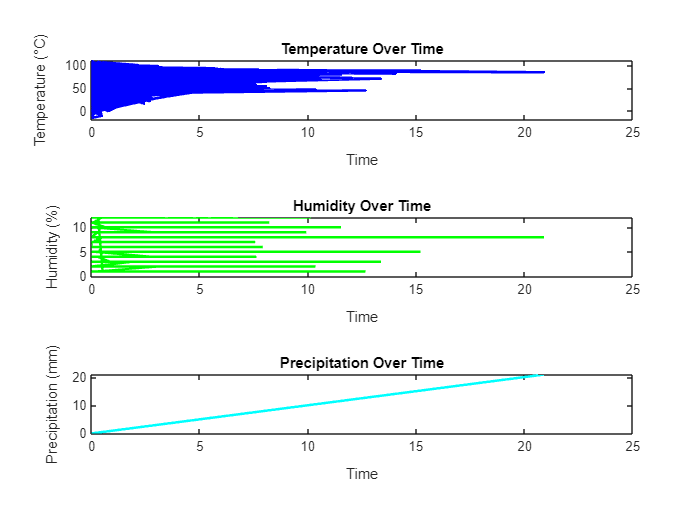

% Define window size for moving average (e.g., 7 for weekly averages)
windowSize = 7;

% Apply moving averages
temp_smooth = movmean(temperature, windowSize);
hum_smooth = movmean(humidity_prec, windowSize);
wind_smooth = movmean(windSpeed, windowSize);

% Plot smoothed data
figure;

% Smoothed Temperature
subplot(3,1,1);
plot(temp_smooth, '-r', 'LineWidth', 1.5);
title('Smoothed Temperature (7-day Moving Average)');
xlabel('Time');
ylabel('Temperature (°C)');

% Smoothed Humidity
subplot(3,1,2);
plot(hum_smooth, '-m', 'LineWidth', 1.5);
title('Smoothed Humidity (7-day Moving Average)');
xlabel('Time');
ylabel('Humidity_prec (%)');

% Smoothed Precipitation
subplot(3,1,3);
plot(wind_smooth, '-k', 'LineWidth', 1.5);
title('Smoothed windSpeed (7-day Moving Average)');
xlabel('Time');
ylabel('Precipitation (m/s)');

## **Co-relation**

% Assuming 'weatherMatrix' contains the data
% Extract columns for analysis
temperature = weatherMatrix(:, 11);
humidity_prec = weatherMatrix(:, 1);
windSpeed = weatherMatrix(:, 14);

% Combine data into a matrix
dataMatrix = [temperature, humidity_prec, windSpeed];

% Compute correlation matrix
correlationMatrix = corrcoef(dataMatrix);

% Display the correlation matrix
disp('Correlation Coefficients:');

Correlation Coefficients:


disp(correlationMatrix);

    1.0000    0.0694   -0.1958
    0.0694    1.0000   -0.0031
   -0.1958   -0.0031    1.0000



## Scatter plot 

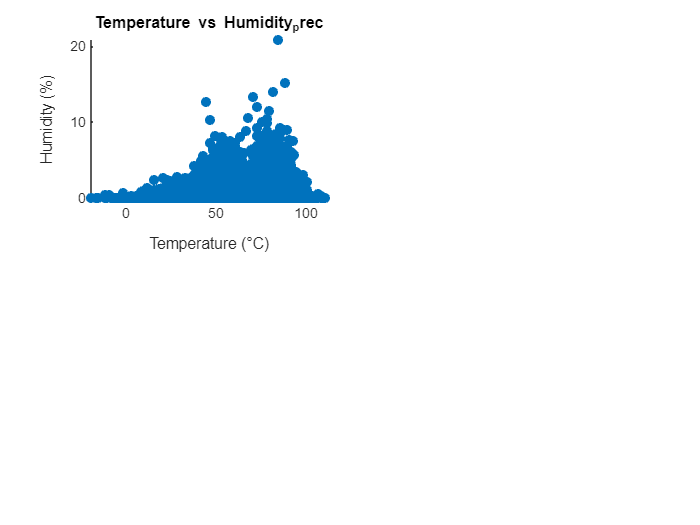

% Create scatter plots
figure;

% Temperature vs Humidity
subplot(2, 2, 1);
scatter(temperature, humidity_prec, 'filled');
title('Temperature vs Humidity_prec');
xlabel('Temperature (°C)');
ylabel('Humidity (%)');

## Linear Regression using Polyfit & Polyval 

% Assuming 'weatherMatrix' is the data matrix
% Columns: [Time, Temperature, Humidity, Precipitation]

% Extract relevant columns
temperature = weatherMatrix(:, 11);
humidity_prec = weatherMatrix(:, 1);
windSpeed = weatherMatrix(:, 14);

% Linear regression: Temperature vs. Humidity
coeff_humidity_prec = polyfit(temperature, humidity_prec, 1);  % Fit a linear model
predicted_humidity_prec = polyval(coeff_humidity_prec, temperature);  % Evaluate the model

% Linear regression: Temperature vs. Precipitation
coeff_windSpeed = polyfit(temperature, windSpeed, 1);  % Fit a linear model
predicted_windSpeed = polyval(coeff_windSpeed, temperature);  % Evaluate the model


## Plot Data and Regression Lines

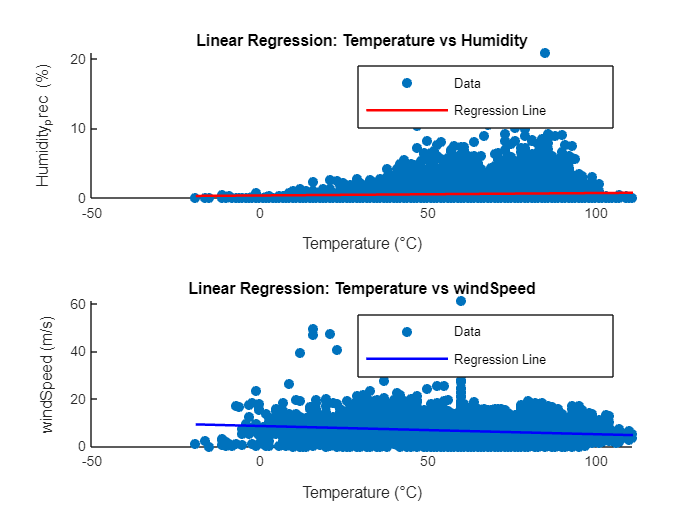

figure;

% Plot: Temperature vs Humidity_prec
subplot(2, 1, 1);
scatter(temperature, humidity_prec, 'filled');  % Original data points
hold on;
plot(temperature, predicted_humidity_prec, '-r', 'LineWidth', 1.5);  % Regression line
hold off;
title('Linear Regression: Temperature vs Humidity');
xlabel('Temperature (°C)');
ylabel('Humidity_prec (%)');
legend('Data', 'Regression Line');


% Plot: Temperature vs windSpeed
subplot(2, 1, 2);
scatter(temperature, windSpeed, 'filled');  % Original data points
hold on;
plot(temperature, predicted_windSpeed, '-b', 'LineWidth', 1.5);  % Regression line
hold off;
title('Linear Regression: Temperature vs windSpeed');
xlabel('Temperature (°C)');
ylabel('windSpeed (m/s)');
legend('Data', 'Regression Line');

## 3D surface plot for Temparature variation

% Simulated data for spatial variation
[x, y] = meshgrid(1:10, 1:10);  % Create a 10x10 grid
z = rand(10, 10) * 10 + 20;      % Simulated temperature data

% Create 3D surface plot
figure;
surf(x, y, z);
title('Temperature Variation Over Space');
xlabel('X Coordinate');
ylabel('Y Coordinate');
zlabel('Temperature (°C)');
colormap('jet'); % Use a color map
colorbar;

## 3D Mesh plot for temparature variation

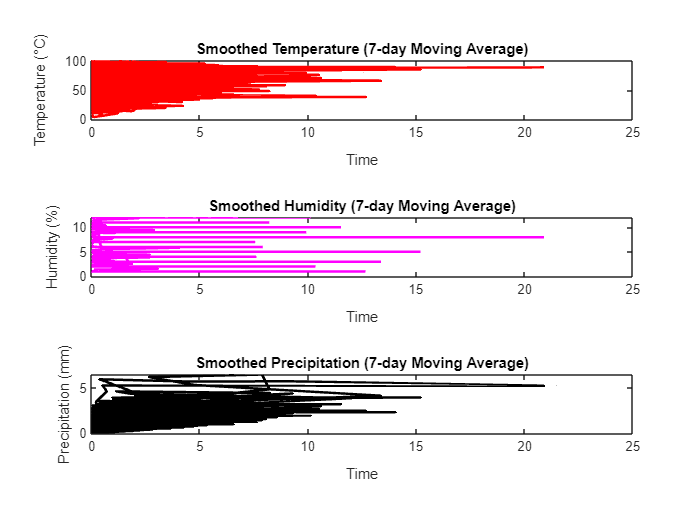

figure;
mesh(x, y, z);
title('Temperature Variation Over Space (Mesh Plot)');
xlabel('X Coordinate');
ylabel('Y Coordinate');
zlabel('Temperature (°C)');
colormap('hot'); % Use a different color map
colorbar;